%Q4

%a

%TF
%note that negative feedback was assumed so the formula for the TF is
%TF = G/(1+G) where G is the given transfer function
G = tf(10 ,[1,6,8,10])

G =
 
            10
  ----------------------
  s^3 + 6 s^2 + 8 s + 10
 
Continuous-time transfer function.



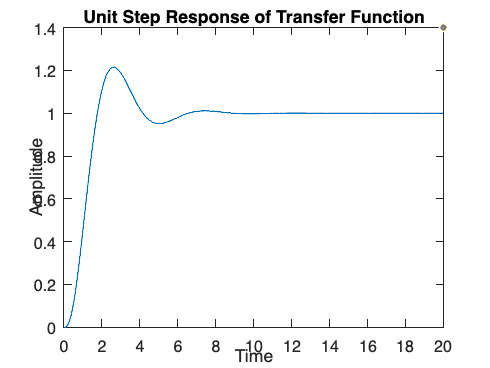


%Time
start = 0;
stop = 20;
scale = 1000;
t = linspace(start, stop, stop*scale);

%graph
[y, t2] = step(G,t);
plot(t2,y)
title('Unit Step Response of Transfer Function')
xlabel('Time')
ylabel('Amplitude')


%b

%calculate overshoot and peaktime
S = stepinfo(G);
%prints max overshoot and peaktime
disp(S)

         RiseTime: 1.1097
    TransientTime: 5.9972
     SettlingTime: 5.9972
      SettlingMin: 0.9226
      SettlingMax: 1.2144
        Overshoot: 21.4419
       Undershoot: 0
             Peak: 1.2144
         PeakTime: 2.6014

